# Analisi relazione 4

R = [4.625 11.898 17.998 23.947].*10^3;
C1 = 150*10^(-9);
C2 = 10*10^(-9);
Tcalc1 = (1.1*C1).*R;
Tcalc2 = (1.1*C2).*R;
Tmeas1 = [0.772 1.99 3.00 4.00].*10^(-3);
Tmeas2 = [53.2 135 207 270].*10^(-6);
e1 = ((abs(Tcalc1-Tmeas1)./Tcalc1).*100)

e1 =     1.1630    1.3667    1.0213    1.2337


e2 = ((abs(Tcalc2-Tmeas2)./Tcalc2).*100)

e2 =     4.5700    3.1495    4.5571    2.4991


## C = 150nF - Plot reale vs misurato

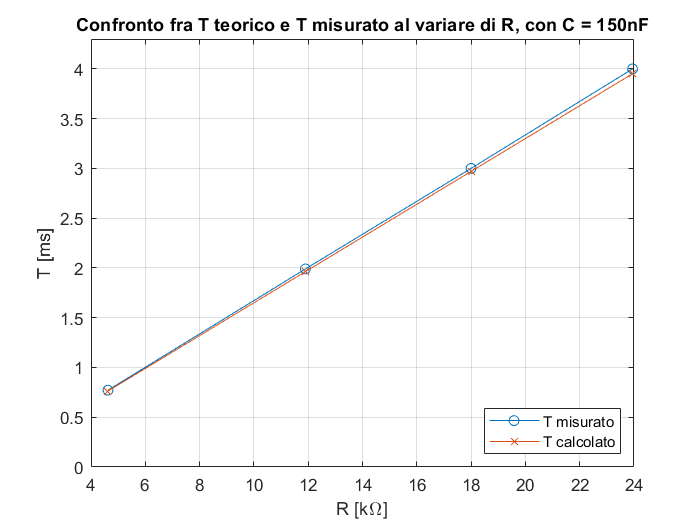

figure
plot(R./10^(3),Tmeas1.*10^(3),'-o')
hold on
grid on
plot(R./10^(3),Tcalc1.*10^(3),'-x')
title('Confronto fra T teorico e T misurato al variare di R, con C = 150nF')
xlabel('R [k\Omega]'); ylabel('T [ms]')
ylim([0 4.3]);
legend('T misurato','T calcolato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 4\TexFiles\immagini\graficomis1.png');

## C = 10nF - Plot reale vs misurato

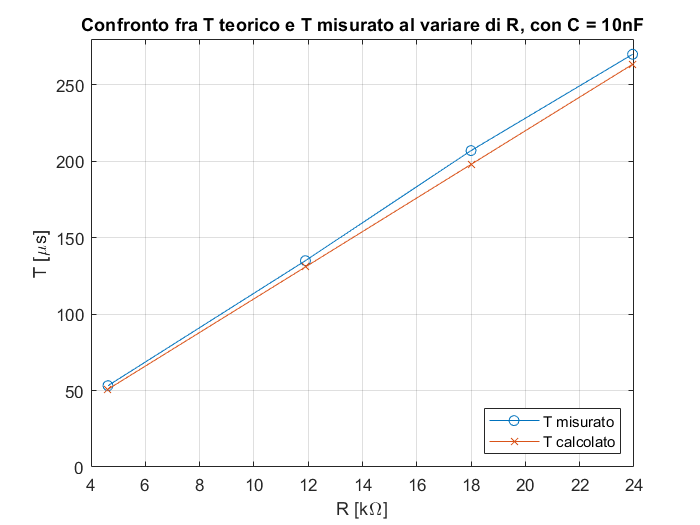

figure
plot(R./10^(3),Tmeas2.*10^(6),'-o')
hold on
grid on
plot(R./10^(3),Tcalc2.*10^(6),'-x')
title('Confronto fra T teorico e T misurato al variare di R, con C = 10nF')
xlabel('R [k\Omega]'); ylabel('T [\mus]')
ylim([0 280]);
legend('T misurato','T calcolato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 4\TexFiles\immagini\graficomis2.png');

## Confronto fra i due grafici misurati

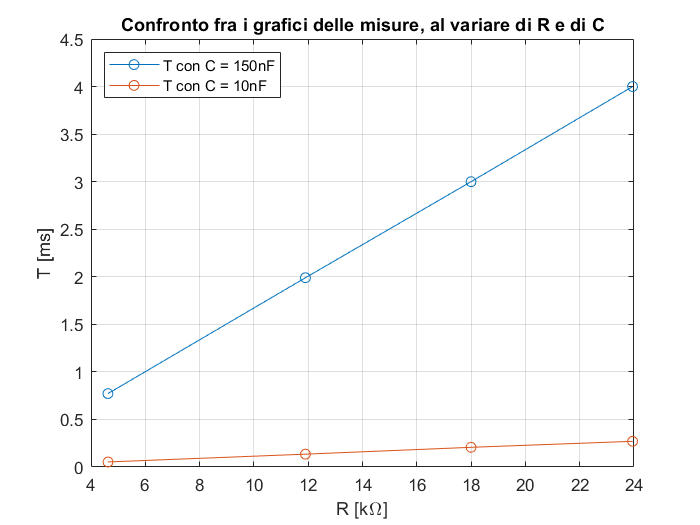

figure
plot(R./10^(3),Tmeas1.*10^(3),'-o')
hold on
grid on
plot(R./10^(3),Tmeas2.*10^(3),'-o')
title('Confronto fra i grafici delle misure, al variare di R e di C')
xlabel('R [k\Omega]'); ylabel('T [ms]')
ylim([0 4.5]);
legend('T con C = 150nF','T con C = 10nF','Location','northwest')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 4\TexFiles\immagini\graficoconfronto1.png');